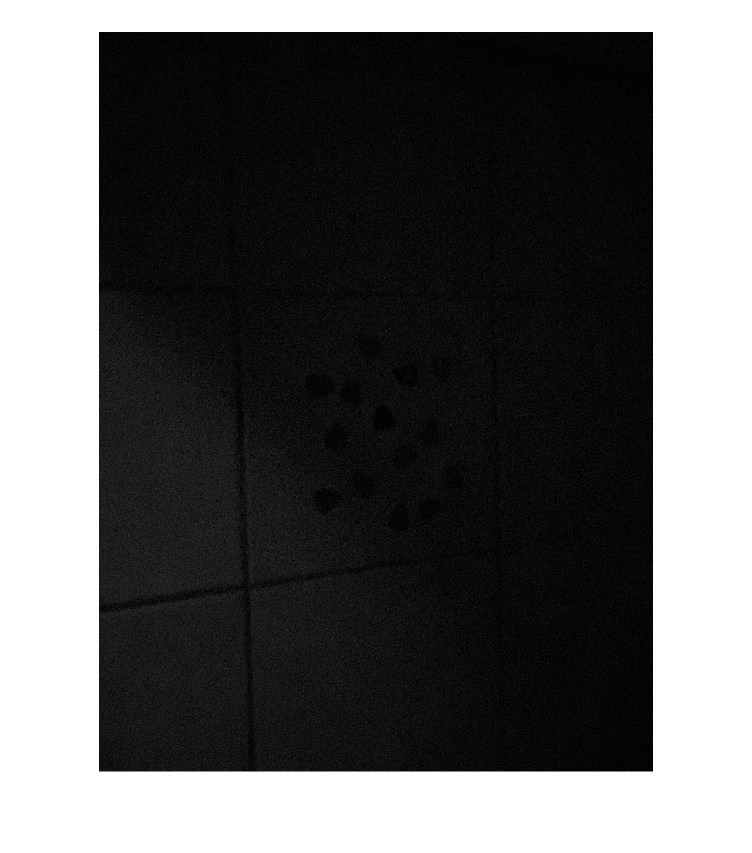

img = im2double(im2gray(imread("picks.jpg")));
imshow(img);

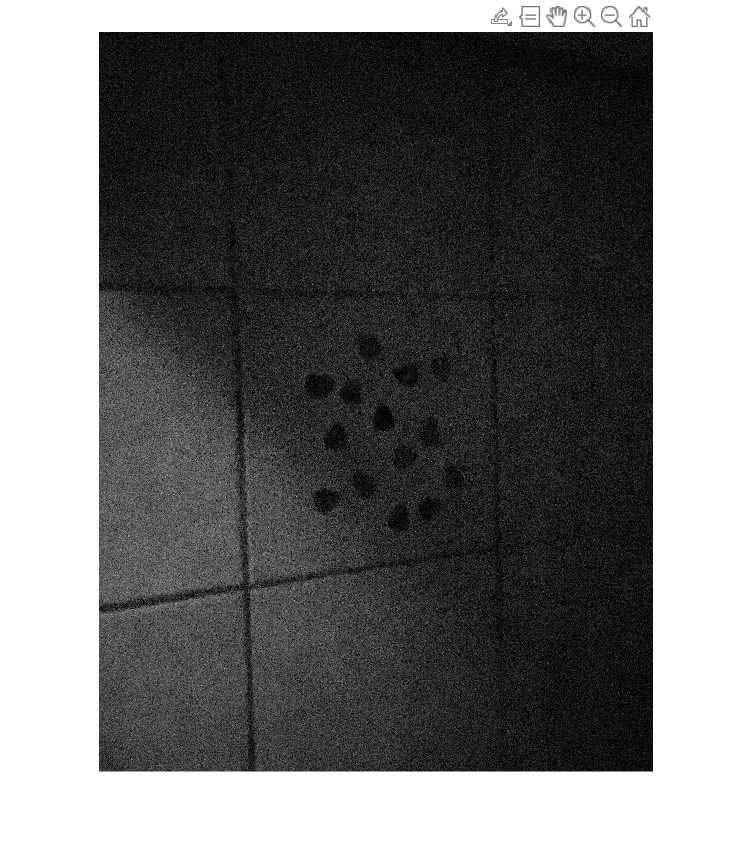

[R, C] = size(img);
outputimg = zeros(R,C);
L = 256;
rmin = min(min(img));
rmax = max(max(img));
diff = rmax - rmin;
for i = 1:1:R
    for j = 1:1:C
        outputimg(i,j) = ((img(i, j) - rmin)/diff) * (L - 1);
    end
end
imshow(outputimg,[])